## Project #1

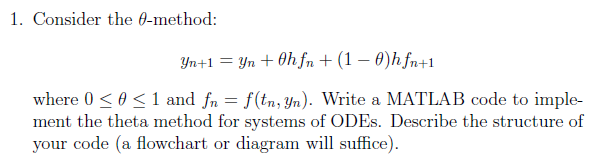

This is a flowchart describing the algorithm I have written:

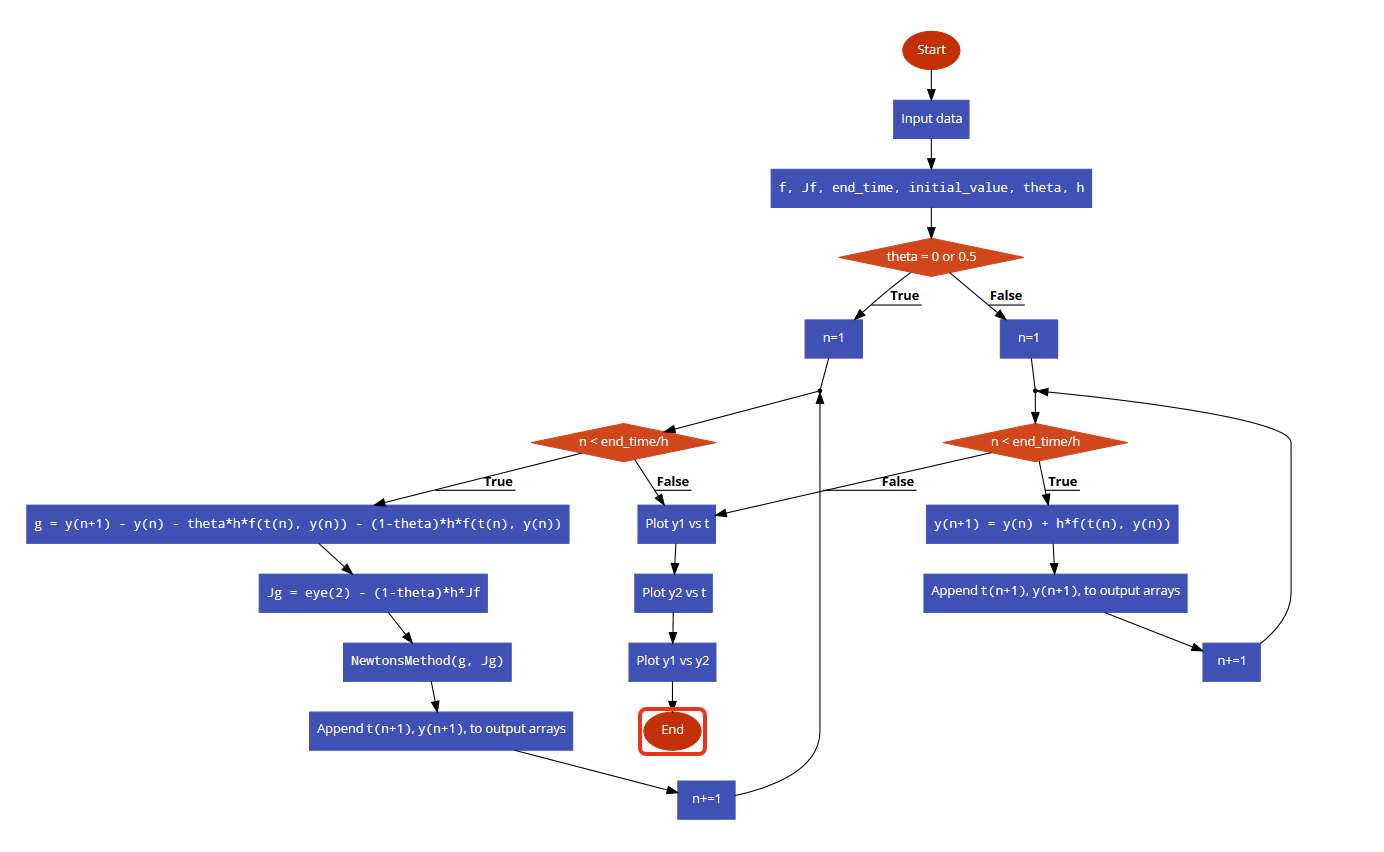

## Problem 1

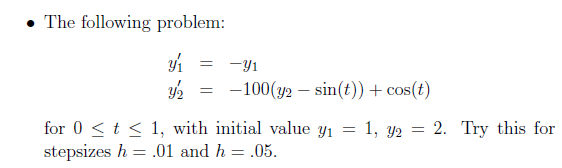

% The given data
f = @(t,y1,y2)[-y1;-100*(y2-sin(t))+cos(t)];
Jf = [-1,0;0,-100]; % Jacobian of f. No need to have the software compute 
                    % it since it's constant. 
end_time = 1;
y_initial = [1;2];
plot_on = false; % I've manually inserted photos of the results so I can 
% better control the formatting. Change this to true if you want to verify 
% the output for yourself.

for h= [0.05, 0.01]
    for theta = [0, 0.5, 1]
        % Theta method starts here
        
        % Initialize variables
        start_time = 0;
        time = start_time;
        t_out = [start_time];    % These are the output data. We will graph
        y1_out = [y_initial(1)]; % y1_out and y2_out versus t_out.
        y2_out = [y_initial(2)];
        Jg = @(y1, y2) eye(2)  - (1-theta)*h*Jf;
                
        % Compute values
        for n = 1:(end_time/h) %n matches the column index of output which was last filled.
            time = time + h; %increment time
            t_out = [t_out, time]; % append to time output
            if theta ~= 1 % backward euler or trapezoidal method                
                g = @(y1,y2)( [y1;y2] - [y1_out(n);y2_out(n)] ...
                    - theta*h*f(time-h,y1_out(n),y2_out(n)) - (1-theta)*h*f(time,y1,y2) );
                %Jg = @(y1, y2) eye(2)  - (1-theta)*h*Jf   
                % No need to run this line over and over, so we do it above 
                % the for block just once.
                
                % Now we compute next y values with Netwon's Method. The
                % code for this function is included at the end of this
                % document.
                new_y = NewtonsMethod(g, Jg, [y1_out(n);y2_out(n)]); 
                
                y1_out = [y1_out, new_y(1)]; % append y to outputs
                y2_out = [y2_out, new_y(2)];
            else % forward Euler method
                new_y = [y1_out(n);y2_out(n)] + h*f(time-h,y1_out(n),y2_out(n));
                y1_out = [y1_out, new_y(1)]; % append y to outputs
                y2_out = [y2_out, new_y(2)];
            end
        end

        p = [t_out; y1_out; y2_out] ; % put all the outputs together for plotting
        
        if plot_on
            figure
            hold on % plot on the same figure
            plot(p(1,:),p(2,:)) % y1 vs t
            plot(p(1,:),p(3,:)) % y2 vs t
            hold off
            xlim([0 end_time]) % stop a weird space from appearing in the plot
            title(strcat('Problem 1, h=', string(h), ', \theta=', string(theta)))
            legend({'y1', 'y2'})
        end
    end
end

### Results

Let's first examine the output when the step size is fairly large:

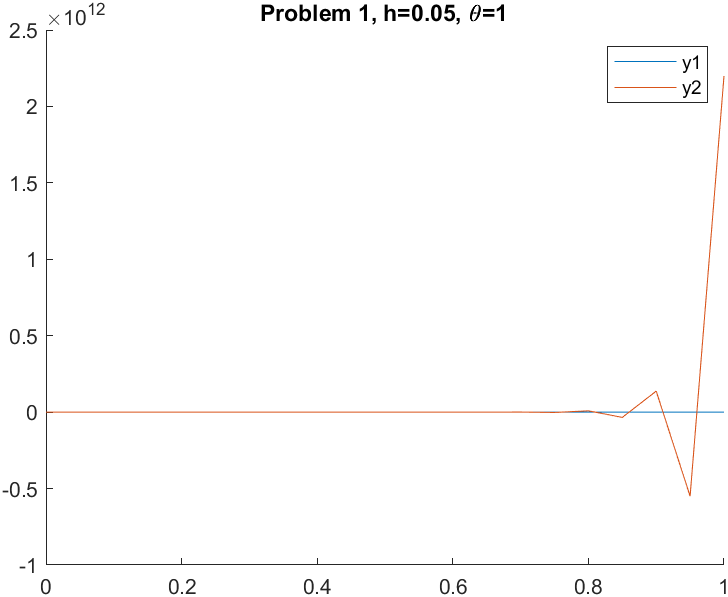

Here we can see that the Forward Euler method has "blown up" for `y2`, it's all the way up at $$10^{12}$$. It's no surprise that this happened, since this problem is stiff.

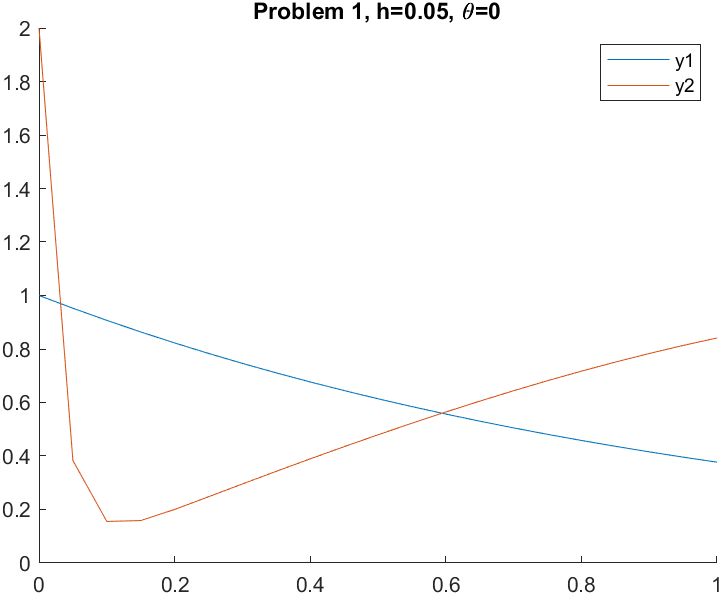

This looks more reasonable; since $y_1' = -y_1$ we expect to see exponential decay in that variable, and 

since $y_2' = -100(y_2-\sin t)+\cos t$ is our stereotypical form for a stiff ODE with smooth solution $\sin t$, 

then we expect a short transient followed by something that looks like $\sin t$. 

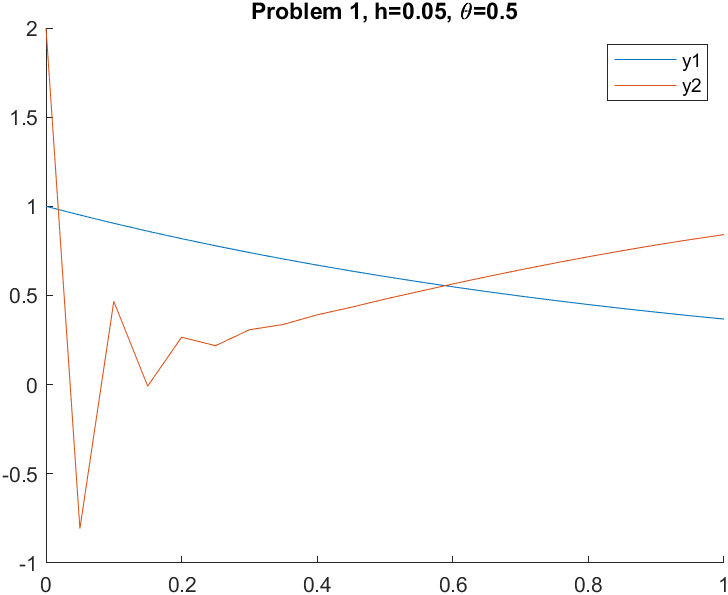

The trapezoidal method has better accuracy but no stiff decay, so it's no surprise that we're still having some stability issues because the problem is so stiff. 

Due to the stiffness, we see that `y_2` is overshooting, causing it to zig-zig above and below the true solution. 

Now let's use a smaller step size:

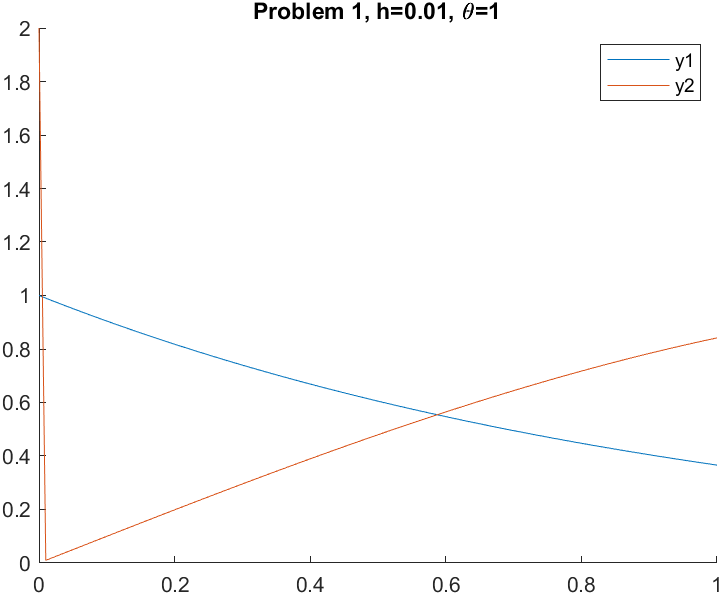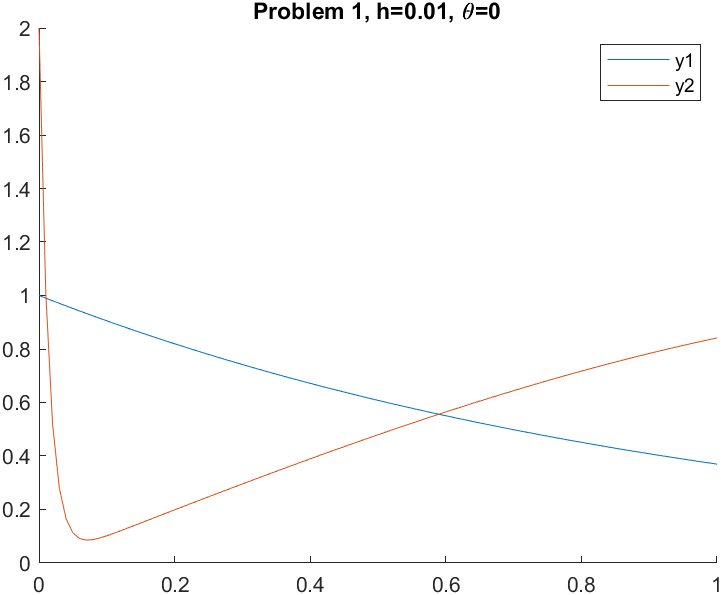

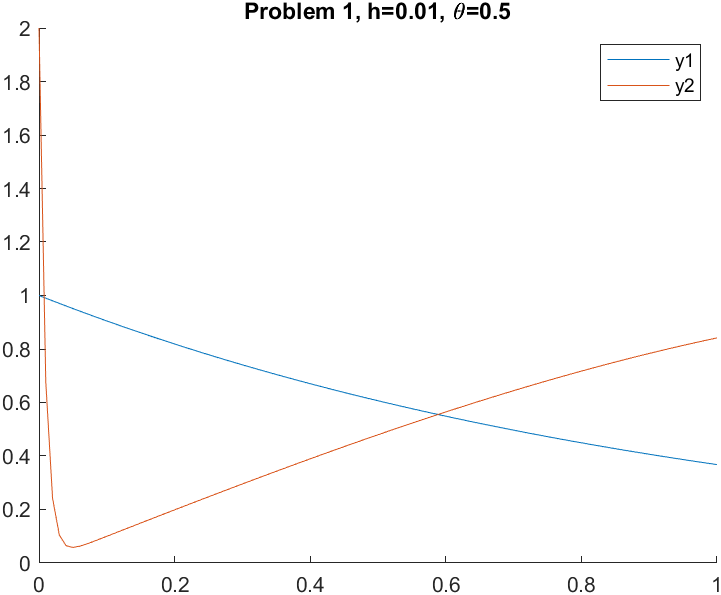

Here we can see all 3 methods show a short transient period, followed by a smooth solution which looks like $\sin t$. I suspect that Forward Euler method is probably exaggerating the transient, and the Trapezoidal Method likely is closest to the true solution, since it has order 2 and we are using a small enough step size to overcome the stability issues. 

It was my assumption that the directions to plot $y_1$ vs $y_2$ only applied to the second problem, but I include them here for completeness. 

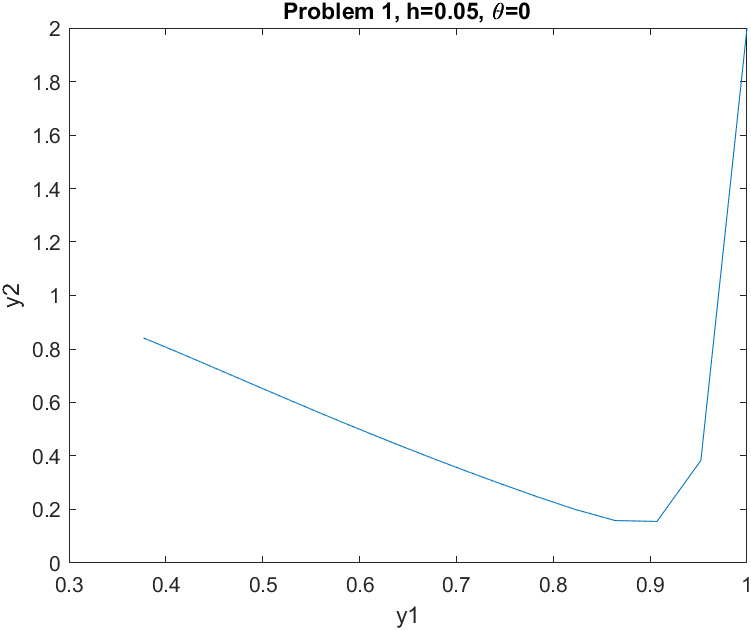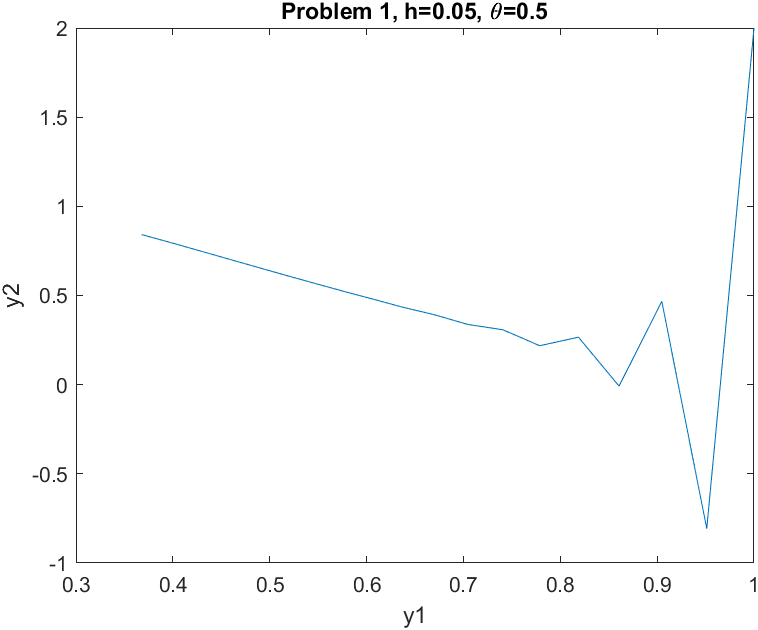

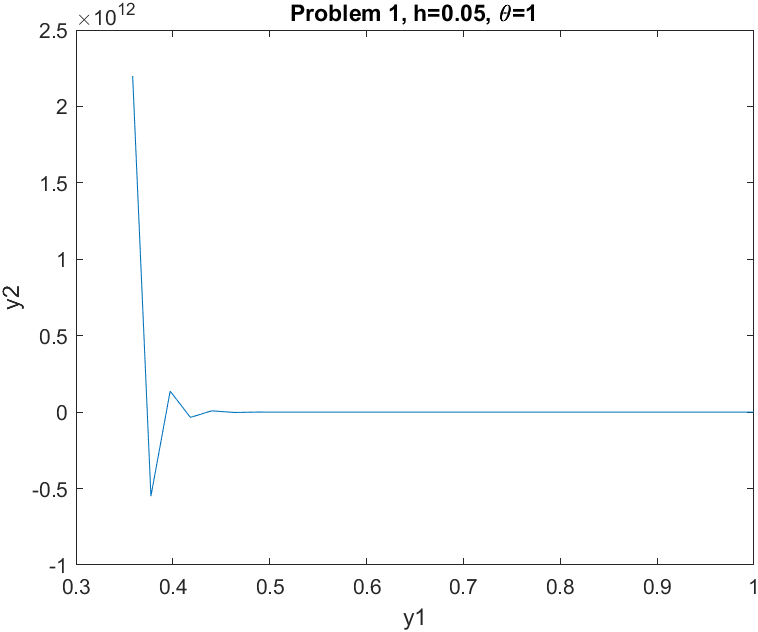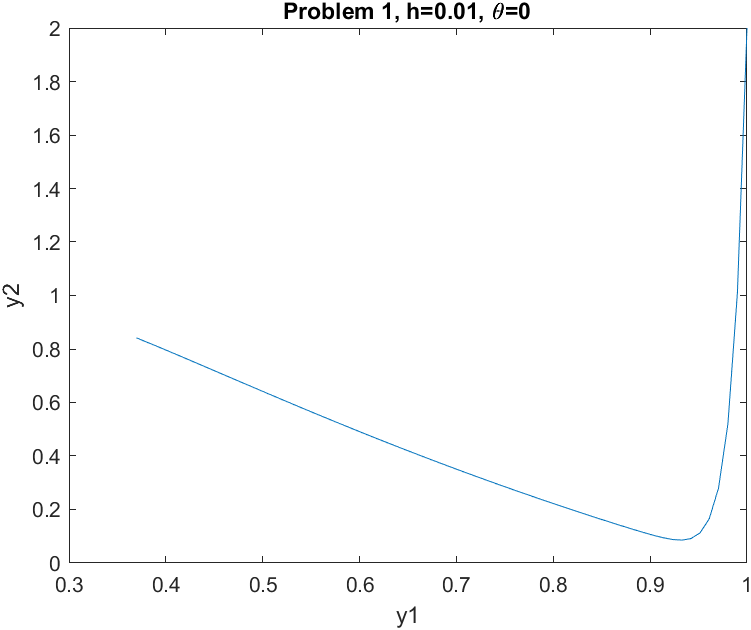

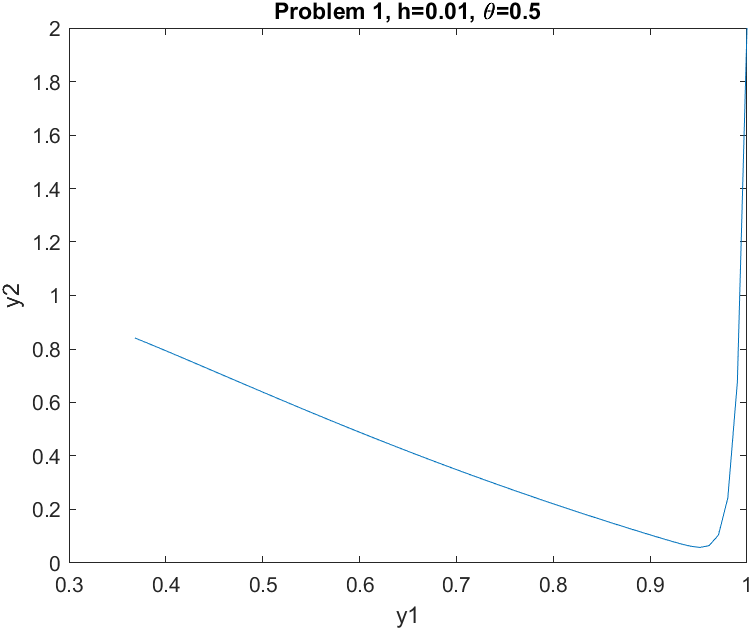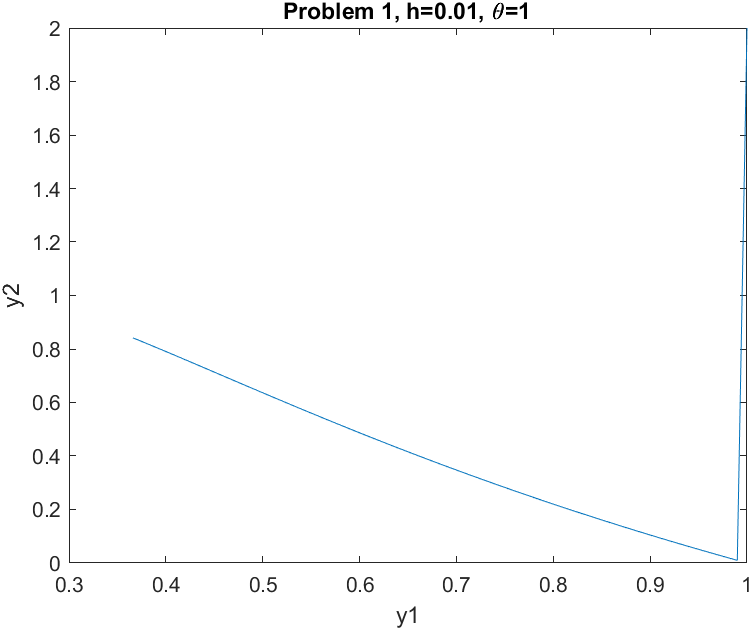

## Problem 2

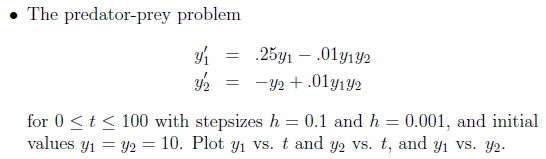

% The given data
f = @(y1,y2)[.25*y1-.01*y1*y2; -y2+.01*y1*y2];
Jf = @(y1,y2)[.25 - .01*y2, -.01*y1; .01*y2, .01*y1 - 1];
end_time = 100;
y_initial = [10;10];
plot_on = false; % I've manually inserted photos of the results so I can 
% better control the formatting. Change this to true if you want to verify 
% the output for yourself.

for h= [0.1, 0.001]
    for theta = [0, 0.5, 1]
        % Theta method starts here
        
        % Initialize variables
        start_time = 0;
        time = start_time;
        t_out = [start_time];    % These are the output data. We will graph y1_out 
        y1_out = [y_initial(1)]; % and y2_out versus t_out.
        y2_out = [y_initial(2)];
        Jg = @(y1, y2) eye(2)  - (1-theta)*h*Jf(y1,y2);
              
        % Compute values
        for n = 1:(end_time/h) %n matches the column index of output which was last filled.
            time = time + h; %increment time
            t_out = [t_out, time]; % append to time output
            if theta ~= 1 % backward euler or trapezoidal method   
                g = @(y1,y2)( [y1;y2] - [y1_out(n);y2_out(n)] ...
                    - theta*h*f(y1_out(n),y2_out(n)) - (1-theta)*h*f(y1,y2) );
                %Jg = @(y1, y2) eye(2)  - (1-theta)*h*Jf(y1,y2)
                % No need to run this line over and over, so we do it above 
                % the for block just once.

                % Now we compute next y values with Netwon's Method. 
                new_y = NewtonsMethod(g, Jg, [y1_out(n);y2_out(n)]);
                y1_out = [y1_out, new_y(1)]; % append y to outputs
                y2_out = [y2_out, new_y(2)];
            else % forward Euler method
                new_y = [y1_out(n);y2_out(n)] + h*f(y1_out(n),y2_out(n));
                y1_out = [y1_out, new_y(1)]; % append y to outputs
                y2_out = [y2_out, new_y(2)];
            end %if
        end %for n

        p = [t_out; y1_out; y2_out] ; % put all the outputs together for plotting

        if plot_on    
            figure
            hold on % plot on the same figure
            plot(p(1,:),p(2,:)) % y1 vs t
            plot(p(1,:),p(3,:)) % y2 vs t
            hold off
            xlim([0 end_time]) % stop a weird space from appearing in the plot
            title(strcat('Problem 2, h=', string(h), ', \theta=', string(theta)))
            legend({'y1', 'y2'})

            figure
            %hold on
            plot(p(2,:),p(3,:)) %y2 vs y1
            %hold off
            title(strcat('Problem 2, h=', string(h), ', \theta=', string(theta)))
            xlabel('y1')
            ylabel('y2')   
        end 
    end 
end 

### Stiffness

One thing I want to consider is whether or not this is a stiff problem. Let's look at the eigenvalues of the jacobian of $f$, where $y' = f(t, y_1, y_2)$. 

syms t y1 y2
f = [.25*y1-.01*y1*y2; -y2+.01*y1*y2]

$$f = \left(\begin{array}{c} \frac{y_{1}}{4}-\frac{y_{1}\,y_{2}}{100}\\ \frac{y_{1}\,y_{2}}{100}-y_{2} \end{array}\right)$$

Just by eyeballing it here, none of the coefficients of $f$ are very large, so I don't expect the eigenvalues to be large either. Let's compute:

J = jacobian(f, [y1, y2])

$$J = \left(\begin{array}{cc} \frac{1}{4}-\frac{y_{2}}{100} & -\frac{y_{1}}{100}\\ \frac{y_{2}}{100} & \frac{y_{1}}{100}-1 \end{array}\right)$$

eig(J)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{y_{1}}{200}-\frac{y_{2}}{200}-\sigma_{1}-\frac{3}{8}\\ \frac{y_{1}}{200}-\frac{y_{2}}{200}+\sigma_{1}-\frac{3}{8} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\frac{{y_{1}}^{2}}{10000}-\frac{y_{1}\,y_{2}}{5000}-\frac{y_{1}}{40}+\frac{{y_{2}}^{2}}{10000}-\frac{y_{2}}{40}+\frac{25}{16}}}{2} \end{array}$$

So since (as we will see) $y_1
$ and $y_2$ are between 0 and 350, neither of these eigenvalues are very extreme, with real parts on the order of -1. However, the time interval is 100, so it's hard to say wether or not this problem is stiff without trying it. 

### Results

As in Problem 1, let's begin with the larger step size:

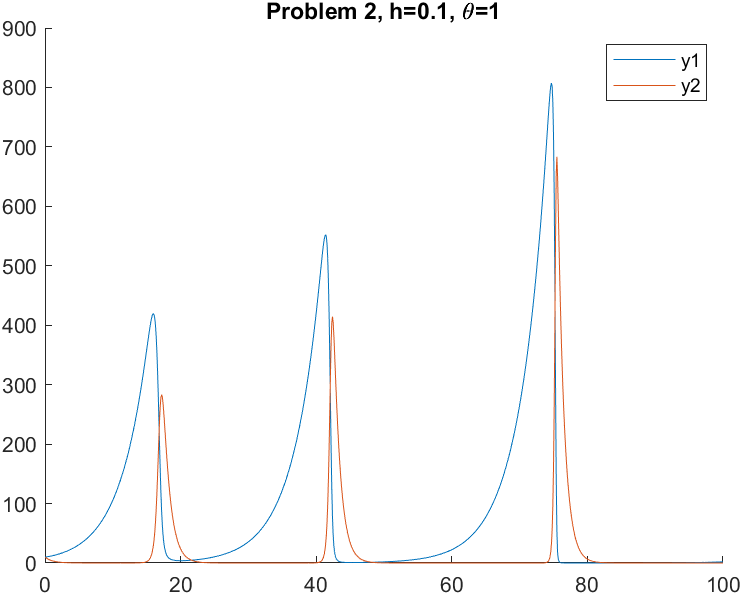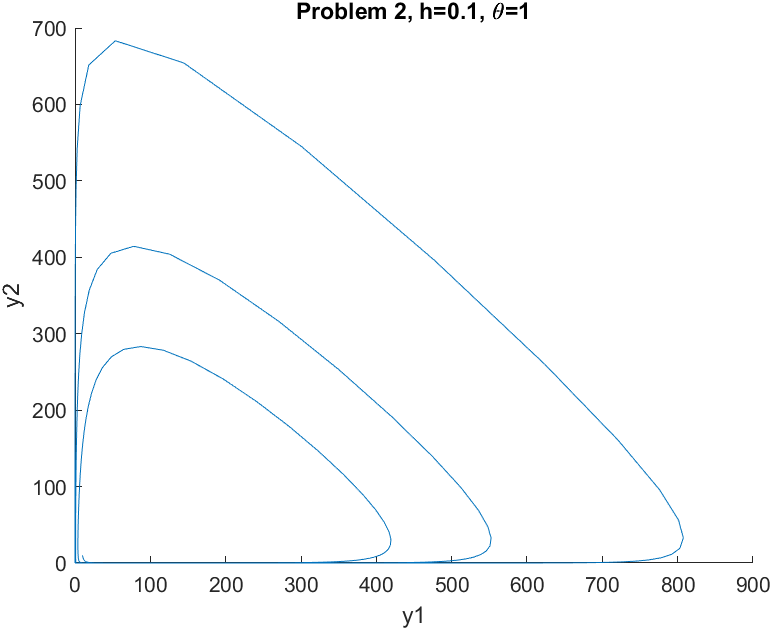

So here we see that in the Forward Euler Method with stepsize 0.1, it doesn't blow up or oscillate wildly, but it doesn't look right either. We know to expect a periodic solution with  predator-prey systems, but in the y1 vs y2 plot, we see the loops  growing in magnitude, with the third loop about twice as big as the first one (but not like 10^12 or anything). 

Let's see if the Backwards Euler method does any better, also using a large step size:

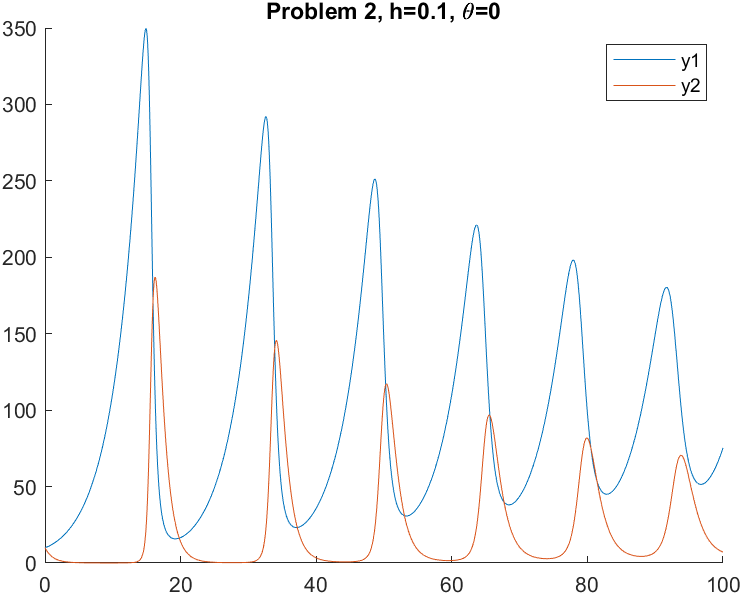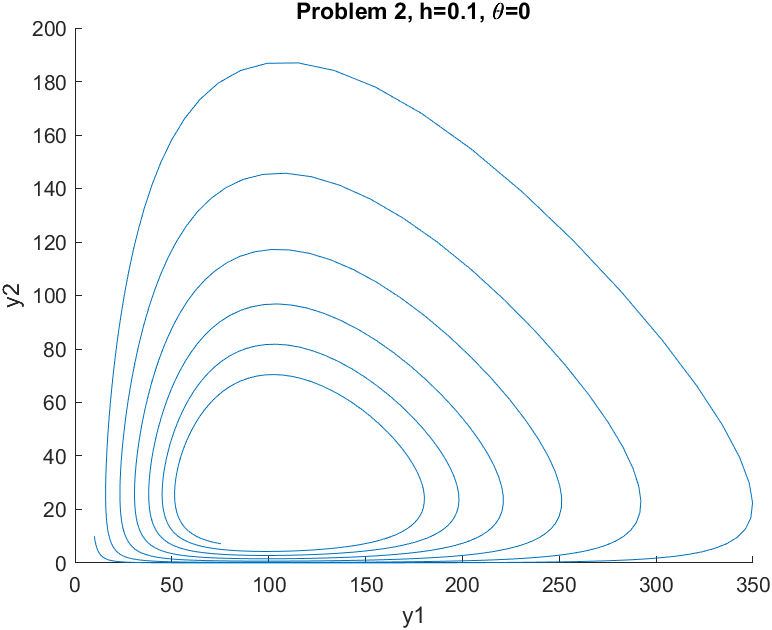

Here we see this is also wrong, since instead of spiraling out, the y1 vs y2 plots spiral in. So we'll need to reduce the step size no matter what to improve accuracy. This tells us that the problem is **not stiff**. Side note: this damping of the oscillations is due to BEM's stiff decay, so we'd really like a method with no stiff decay, but we'll come back to this. 

Following are the results with the Forward Euler Method and a much smaller step size 0.001. Note the first three loops are all almost the same size:

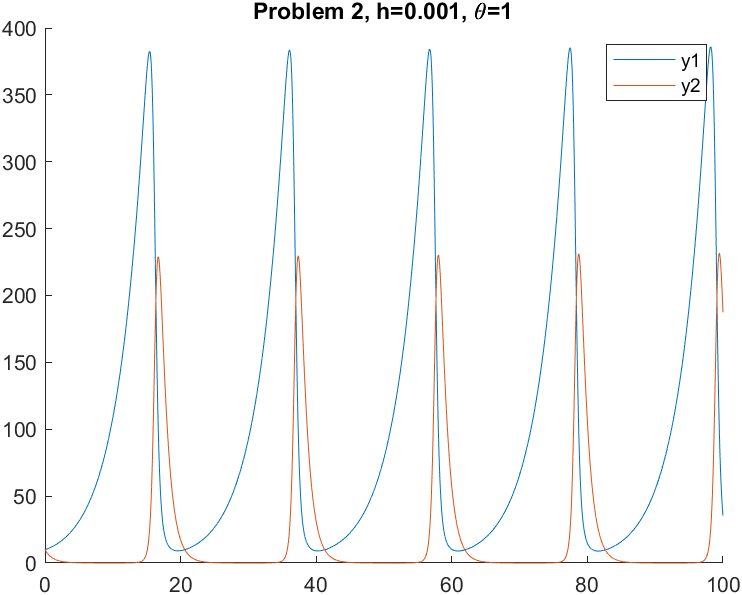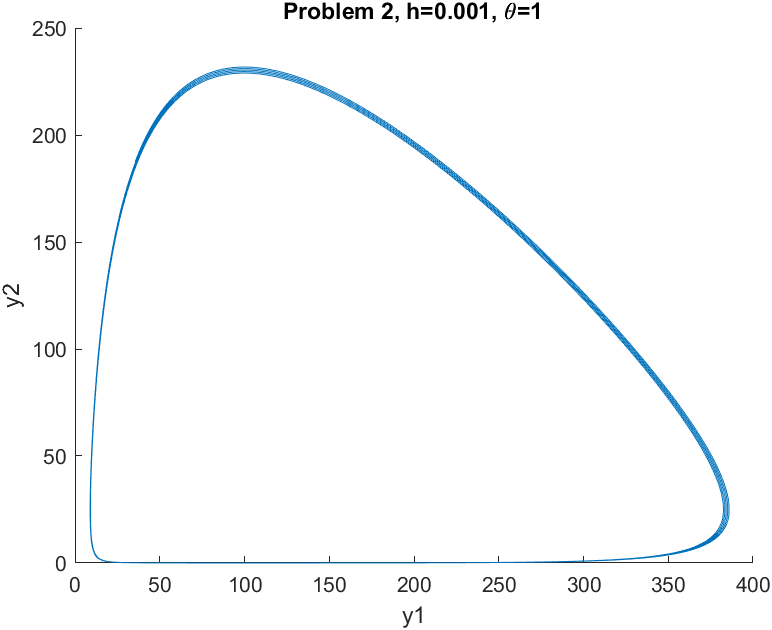

In fact, we probably could just glue together the first period and call that our solution, since FEM is computationally cheap and we have pretty solid results. 

But of course we will try everything here in the project for the sake of comparison. Here's BEM at h=0.001 (note how we get almost exactly the same results):

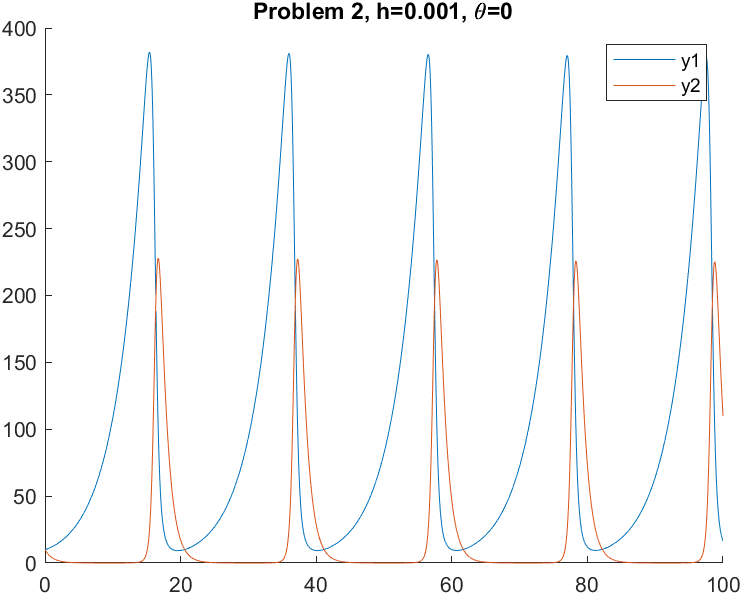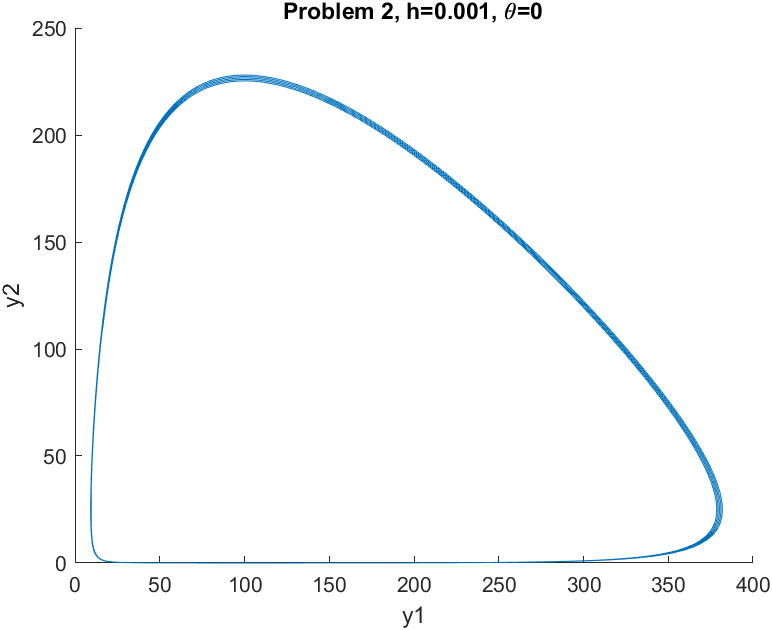

So far we haven't discussed the Trapezoidal Method. Trapezoidal method is probably the best choice in the first place for this problem, since we knew at the start that we were expecting an oscillatory solution, and we know that Trapezoidal Method is 2nd order and has no stiff decay. Here are the results for h =0.1, the big step size:

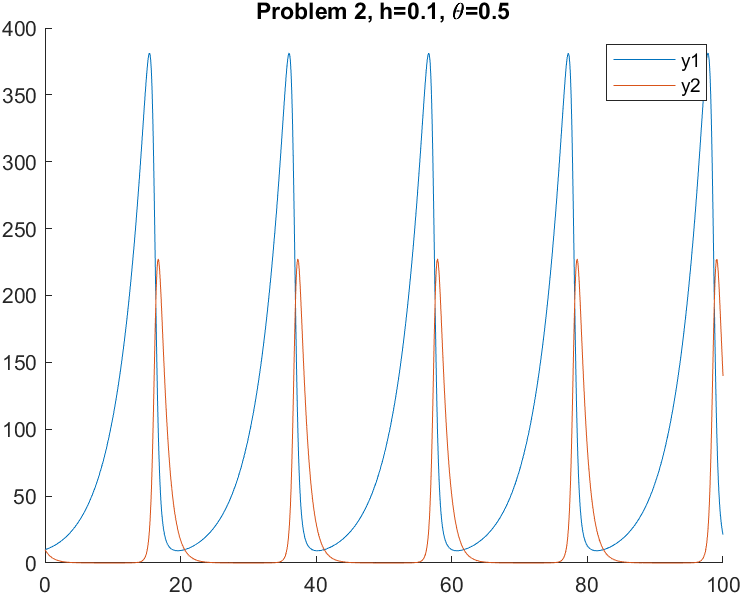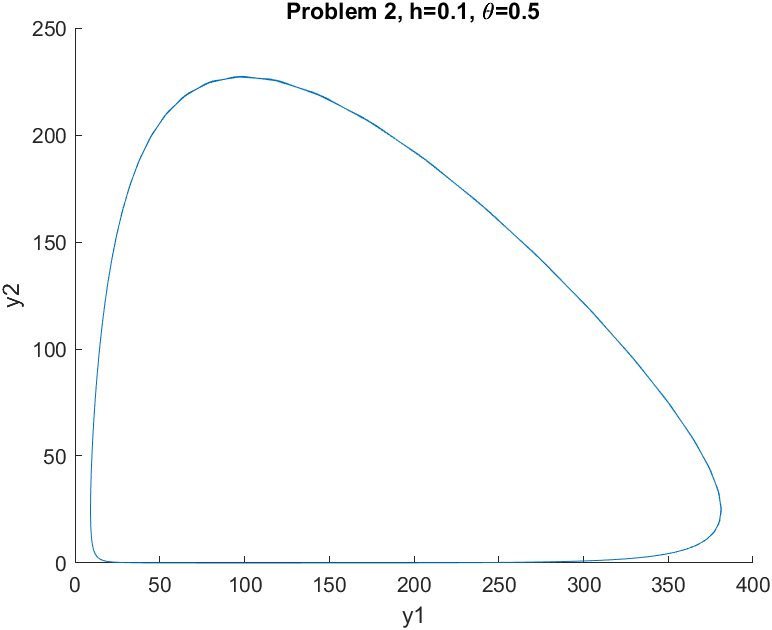

Even better than the small step sizes for FEM and BEM!! Here's the small step size Trapezoidal Method, which gives almost indistinguishable results:

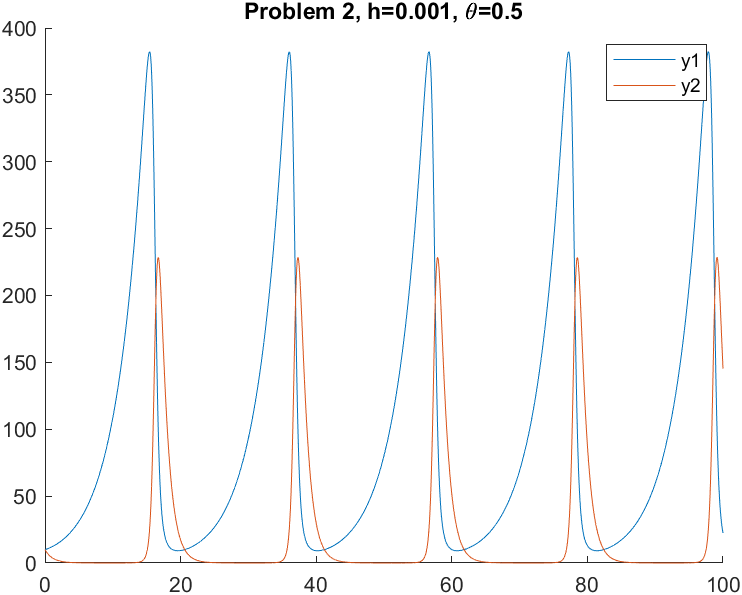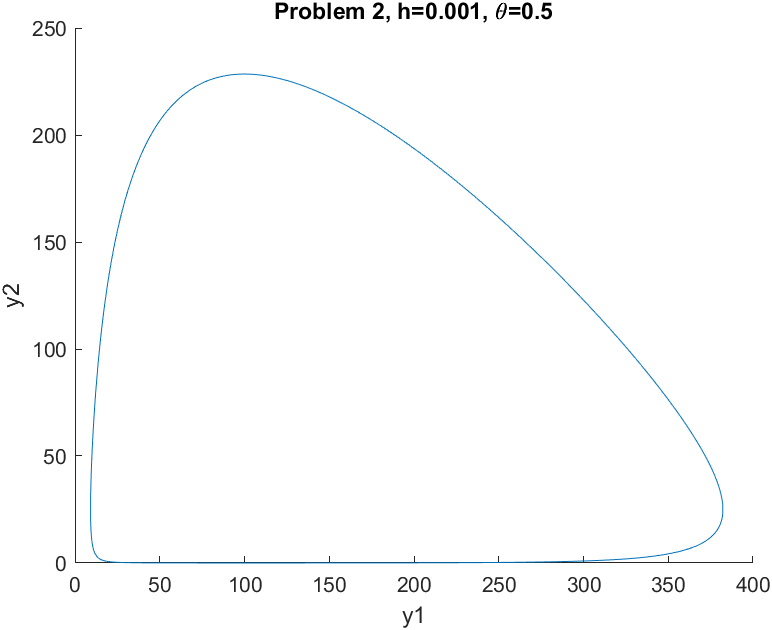

The brilliant performance of the Trapezoidal method, even with a large step size, really impressed me here. TM with h=0.1 ran in 0.166 seconds, whereas FEM with h=0.001 ran in 50.9 seconds and got worse results.

## Appendix

This document was composed as a MATLAB LiveScript and exported as PDF. Also submitted with this PDF is `Project1_klar.m`, which is a standard MATLAB script that can be run to replicated the results if desired. 

To facilitate reviewing the code if running it is not necessary, I have included below the code for `NewtonsMethod()`:

function output = NewtonsMethod(F, J, root_guess)
%NewtonsMethod Finds a root of a function [F1(y1, y2); F2(y1, y2)] via Newton's Method
%   we're expecting F and J to be matlab functions of two variables here.
%   Here we require J to be computed in advance because we don't need a lot
%   of generality and precomputing is faster.

epsilon = 5*10^(-2); %How close to get before terminating

%Initializing variables
delta = [1;1]; % start with some arbitrary nonzero delta (this will change)
y = root_guess;

while norm(delta)>epsilon
    %Plug in
    J_y = J(y(1), y(2));
    F_y = F(y(1), y(2));
    %Solve for delta in the equation (J_y)(delta)=-(F_y)
    delta = double(linsolve(J_y,-F_y));
    y = y + delta;
end %loop until delta <= epsilon
output = y;
end

